# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.12 绘制带斜线填充的曲线图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

**问题解析：**

- 绘制箭头没啥好说的，annotation 函数搞定，值得注意的是，需要将实际坐标转换到 [0, 1] 范围；

- 关键点标记，用 text 函数搞定；

- 斜线填充应该是最麻烦的，目标我还没发现好的方法，用了最笨的方法，用直线一条条填充，需要知道起始点坐标；

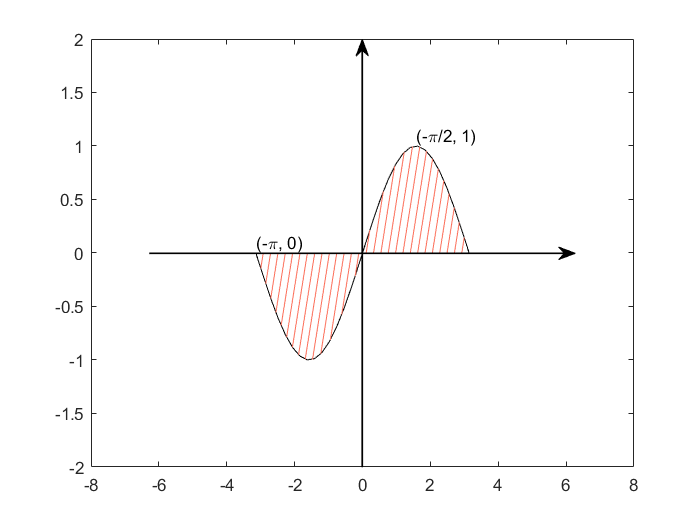

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
syms t
n = 30;
x = linspace(-pi, pi, n);
y = sin(x);
ax = axes;
% 曲线
plot(ax, x, y, 'k');
hold on
% 画带箭头 x 轴和 y 轴
PlotLineArrow(ax, [-2*pi, 2*pi], [0, 0], 'none', 'k', 1);
PlotLineArrow(ax, [0, 0], [-2, 2], 'none', 'k', 1);
% 计算所有的斜线 一条斜线两个点
xx = zeros(1, n);
for i = 1:n
    % 这个方程用来计算斜线的位置
    f1 = 2*(t - x(i));
    f2 = sin(t);
    sol = vpasolve(f1 == f2, t);
    xx(i) = double(sol);
end
yy = sin(xx);
% 画斜线
for i = 1:n
    % 分 x 正负情况
    if x(i) < 0
        plot([xx(i), x(i)], [yy(i), 0], 'Color', all_colors(1, :));
    else
        plot([x(i), xx(i)], [0, yy(i)], 'Color', all_colors(1, :));
    end
end
hold off
% 几个关键点
text(-pi, 0.1, '(-\pi, 0)');
text(pi/2, 1.1, '(-\pi/2, 1)');